hemorRisTable = readtable('./Data/possible-hemorrhages-after-thrombectomy.csv')

hemorRisTable = 961×7 table
    Undersokningsnummer     Undersokningstypsnamn                                                            Fragestallning                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                       Remisstext                                                                                            

risTable = readtable('./Data/all-post-thrombectomy-patients.csv')

risTable = 2050×7 table
    Undersokningsnummer     Undersokningstypsnamn                                           Fragestallning                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                      Remisstext                                                                                                                                  

question = risTable.Fragestallning;
freeText1 = risTable.Remisstext;
freeText2 = risTable.Prioanteckning;
freeText3 = risTable.Utlatandetext;
scanner = risTable.Modalitetsnamn;

freeTextTable = risTable(:,[4,5,6])

freeTextTable = 2050×3 table
                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                               Remisstext                                                                                                                                                                                                                                                                                                                                 


% join all text here
colJoin =  rowfun(@(a,b,c) {strjoin([a,b,c],' ')}, freeTextTable, 'InputVariables', {'Remisstext','Prioanteckning','Utlatandetext'});
fullJoin = string(strjoin(colJoin{:,1},' '));

medCorpus = preprocessText(fullJoin);
rmWords = ["och","med","för","det","har","den","ett","en"];
medCorpus = removeWords(medCorpus,rmWords)

medCorpus =   tokenizedDocument:


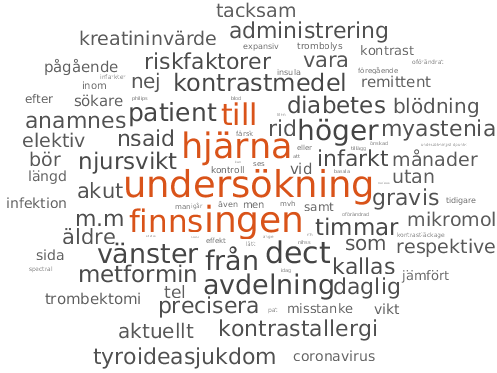

figure
wordcloud(medCorpus);

bag = bagOfWords(medCorpus);

function documents = preprocessText(textData)           
    % Tokenize.
    documents = tokenizedDocument(textData);
    
    % Remove tokens containing digits.
    pat = textBoundary + wildcardPattern + digitsPattern + wildcardPattern + textBoundary;
    documents = replace(documents,pat,"");
    
    % Convert to lowercase.
    documents = lower(documents);
    
    % Remove short words.
    documents = removeShortWords(documents,2);
    
    % Remove stop words.
    documents = removeStopWords(documents);
end